# Homework 7

Names: Dawson Tocarchick, Nicholas Riggins, Kyle Limbaga

## Problem 1

We first introduced the notion of impulse response in Chapter 1, and here in Chapter 5 we discussed the importance of knowing the impulse response of FIR filter networks. With that said, if the y(n) output of a discrete system is equal to the system’s x(n) input sequence: 

(a) Draw the unit impulse response of such a system.

 (b) Draw the block diagram (structure) of that system.

 (c) What is the frequency magnitude response of such a system? Prove your answer

**Answer:**

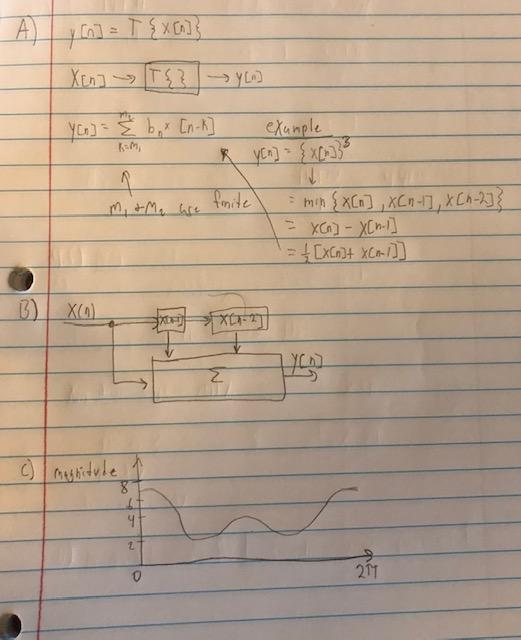

## Problem 2

Consider a simple analog signal defined by x(t) = cos(2π800t) shown in Figure P5-2. The FIR lowpass filter has a passband extending from −400 Hz to +400 Hz, a passband gain of unity, a transition region width of 20 Hz, and a stopband attenuation of 60 dB. 

(a) Draw the spectral magnitude of x(n) showing all spectral components in the range of −2fs to +2fs . 

(b) Draw the spectral magnitude of y(n) showing all spectral components in the range of −2fs to +2fs . 

(c) What is the time-domain peak amplitude of the sinusoidal y(n) output?

**Answer:** 

fs = 1000; %sampling speed
t=0:1/1:fs

x= cos(2*pi*800*t);
fpass= 400;

lowpass(x,fpass,fs);


A)

lowpass(x,fpass,2000);

B)

lowpass(x,fpass,2000);

C) 1.082 is the peak domain ampitude

## Problem 3

Assume we want to filter the audio signal from a digital video disc (DVD) player as shown in Figure P5-3. The filtered audio signal drives, by way of a digital-to-analog (D/A) converter, a speaker. For the audio signal to have acceptable time synchronization with the video signal, video engineers have determined that the time delay of the filter must be no greater than 6×10 −3 seconds. If the fs sample rate of the audio is 48 kHz, what is the maximum number of taps in the FIR filter that will satisfy the time delay restriction? (Assume a linear-phase FIR filter, and zero time delay through the D/A converter.) 

**Answer:**


$$\begin{array}{l}
\frac{1}{2}\left(x-1\right)=\left(6*{10}^{-3} \right)*48000\\
x-1=576\\
x=577
\end{array}$$


The maximum number of taps is 577

## Problem 4

There are times when we want to build a lowpass filter and a highpass filter that are complementary. By “complementary” we mean that a highpass filter’s passband covers the frequency range defined by a lowpass filter’s stopband range. This idea is illustrated in Figure P5- 4(a). An example of such filters is an audio system, shown in Figure P5-4(b), where the lowfrequency spectral components of an x(n) audio signal drive, by way of a digital-to-analog (D/A) converter, a low-frequency speaker (woofer). Likewise, the high-frequency spectral components of x(n) drive a high-frequency speaker (tweeter). Audio enthusiasts call Figure P5-4(b) a “crossover” network. Assuming that the lowpass filter is implemented with a 15-tap FIR filter whose hLow(k) coefficients are those in Figure P5-4(c), the complementary highpass filter will have the coefficients shown in Figure P5-4(d). Highpass coefficients hHigh (k) are defined by

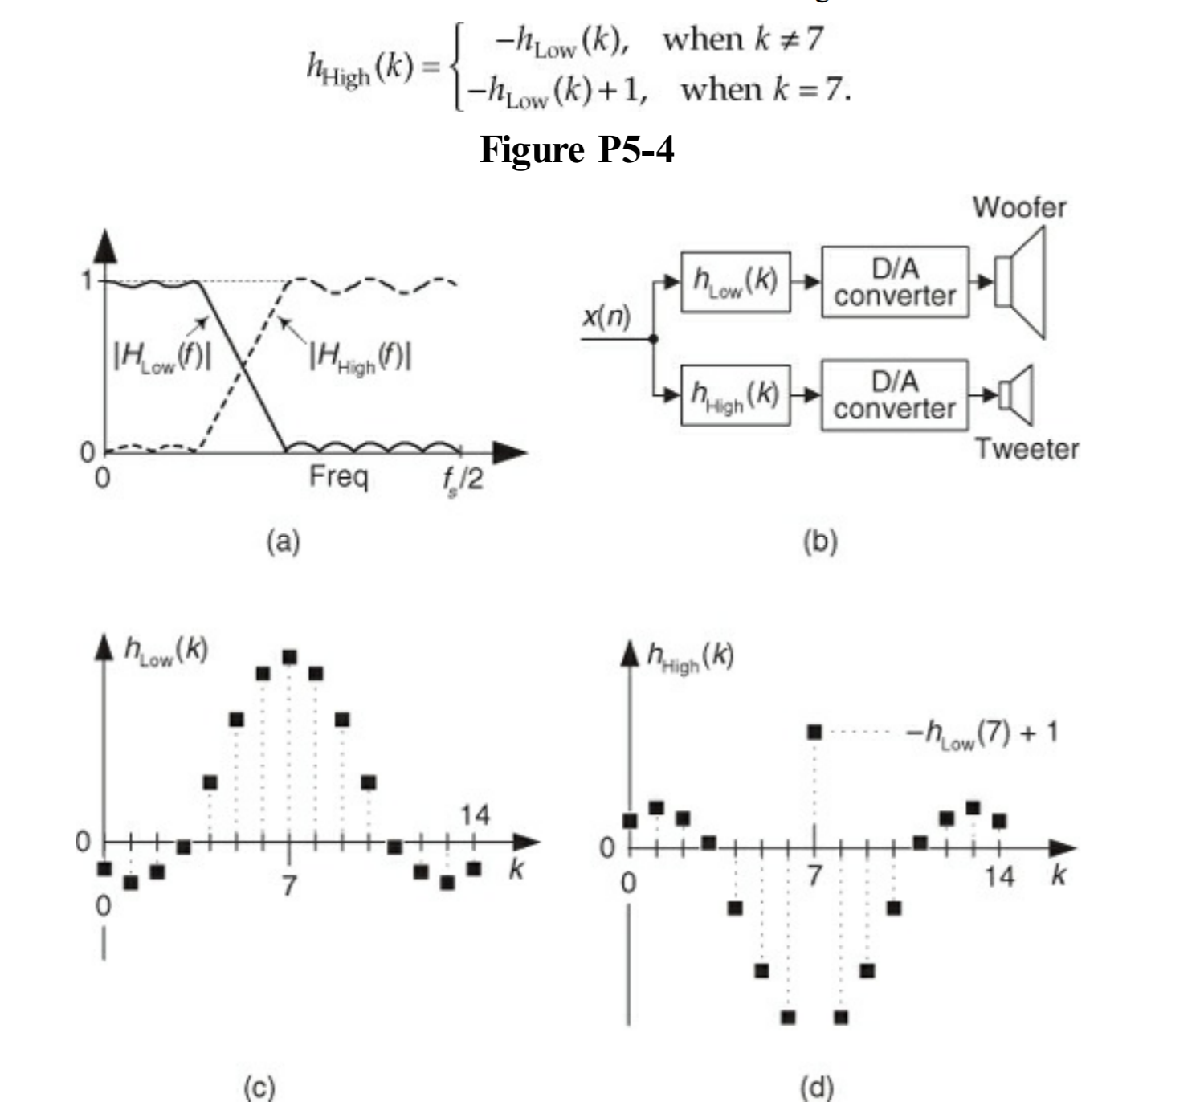

Here is the problem: Draw a block diagram of a system that performs the process in P5-4(b) where only the hLow(k) lowpass FIR filter need be implemented. 

**Answer:** 

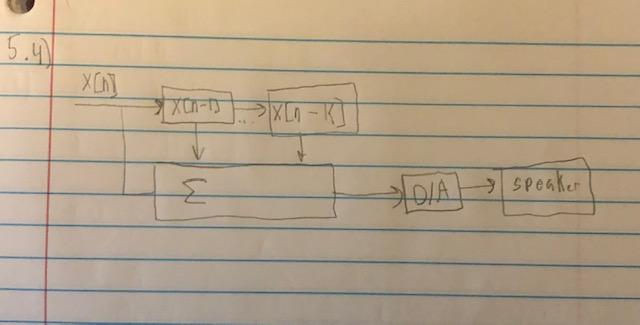

## Problem 5

Think about a discrete System A, shown in Figure P5-5, that has an undesirable amplitude (gain) loss by a factor 0.5 (−6 dB), whose output requires lowpass linear-phase filtering. What can we do in the design of the lowpass FIR filter so the filter has an amplitude gain of 2 to compensate for System A’s amplitude loss?

**Answer:** 

To compensate for system A's amplitude loss a lowpass FIR filtercan be designed so the filter has an amplitude gain of 2. 


$$y\left\lbrack n\right\rbrack =\sum_{K=N}^{M-1} h\left(k\right)x\left(n-k\right)$$



$$\begin{array}{l}
d\left\lbrack n\right\rbrack =\delta \left\lbrack n-1\right\rbrack \\
\left|y\left\lbrack n\right\rbrack \right|=|h\left\lbrack n\right\rbrack *x\left\lbrack n\right\rbrack |
\end{array}$$


from this you get


$$|\sum_{k=-\infty }^{\infty } h\left\lbrack k\right\rbrack *x\left\lbrack n-k\right\rbrack |\le \sum_{k=-\infty }^{\infty } |h\left\lbrack k\right\rbrack *x\left\lbrack n-k\right\rbrack |\le \sum_{k=-\infty }^{\infty } |h\left\lbrack n\right\rbrack |$$


The summation of the last term is finite if h[n] is absolutely summable if it is not absolutely summable consider the signal 

x[n] = sin(h[n])

x[n] is bounded since the only values it takes is -1,0,1

## Problem 6

Let’s assume we have an x(n) time sequence, whose fs sample rate is 20 kHz, and its |X(f)| spectral magnitude is that shown in Figure P5-6(a). We are required to design a linear-phase lowpass FIR filter that will attenuate the undesired high-frequency noise indicated in Figure P5- 6(a). So we design a lowpass FIR filter whose frequency magnitude response is the |H(f)| shown in Figure P5-6(b) and assume our filter design exercise is complete. Sometime later, unfortunately, we learn that the original x(n) sequence’s sample rate was not 20 kHz, but is in fact 40 kHz

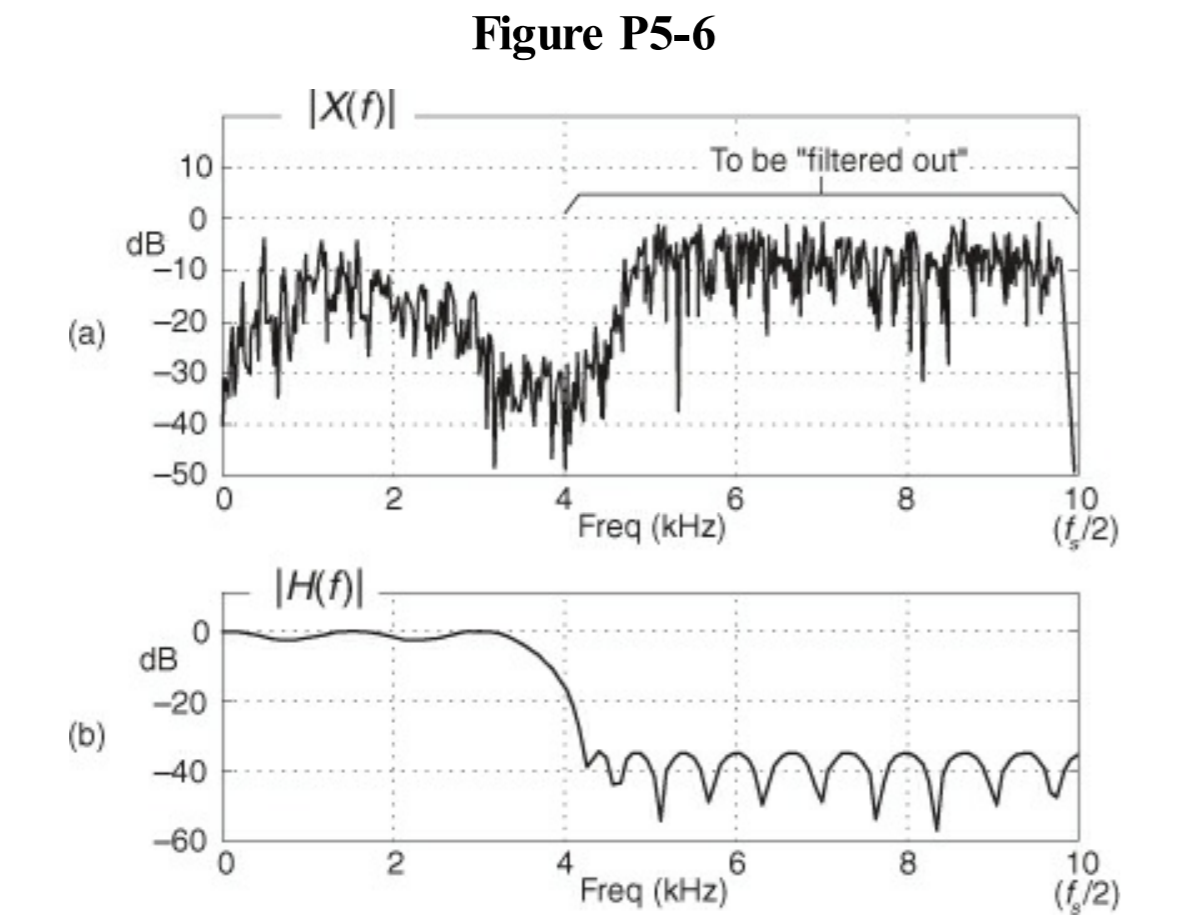

Here is the problem: What must we do to our lowpass filter’s h(k) coefficients, originally designed based on a 20 kHz sample rate, so that they will still attenuate x(n)’s undesired high-frequency noise when the fs sample rate is actually 40 kHz? 

**Answer:** 

For the lowpass filter to work the h(k) coefficient must be divided by 2 because 40kHz is double 20kHz.

## Problem 7

Here is an interesting little problem. Think about applying the sinusoidal input sequence shown in Figure P5-7(a) to an 8-point moving average FIR filter. The filter’s output sequence is that depicted in Figure P5-7(b). 

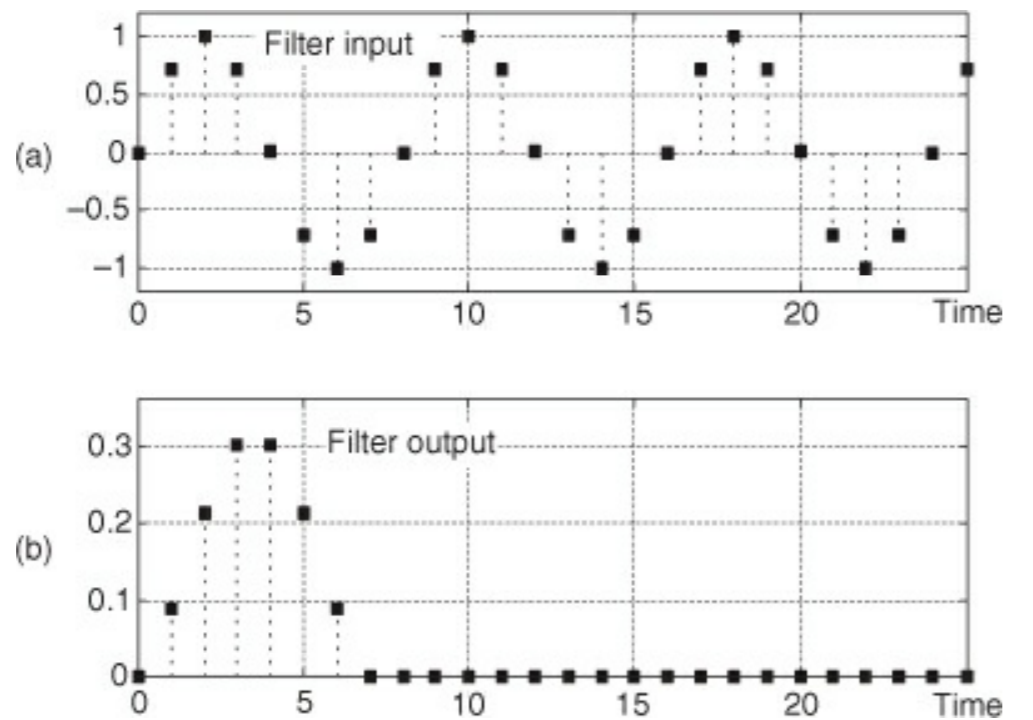

(a) What characteristic of the filter’s frequency response causes the filter’s output sequence to go to all zeros as shown in Figure P5-7(b)?

 (b) In Figure P5-7(b), what do we call those initial nonzero-valued filter output samples? 

**Answer:** 

A) The magnitude resonse reached zero so the gain contribution of the moving average filter at this frequncy is 0

B) The nonzero-valued filter output sample are called  the transient response of the filter

## Problem 8

Are abrupt (sudden) changes in the amplitude of a continuous, or discrete, signal associated with low or high frequencies? 

**Answer:**

Abrupt changes in the amplitude are associated with a high frequency

## Problem 9

Consider an FIR filter whose impulse response is shown in Figure P5-9(a). Given the x(n) filter input sequence shown in Figure P5-9(b):

 (a) What is the length, measured in samples, of the nonzero-valued samples of the filter’s output sequence? 

(b) What is the maximum sample value of the filter’s output sequence? 

**Answers:** 

A) The length of the nonzero-valued samples of the filter's output sequence is 5

B) The maximum sample value of the filter's output sequence is 2

## Problem 10

Consider an FIR filter whose impulse response is that shown in Figure P5-10(a). Given the x(n) filter input sequence shown in Figure P5-10(b), draw the filter’s output sequence. 

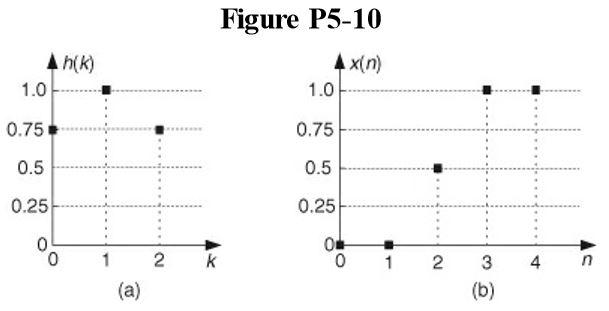

**Answer: **

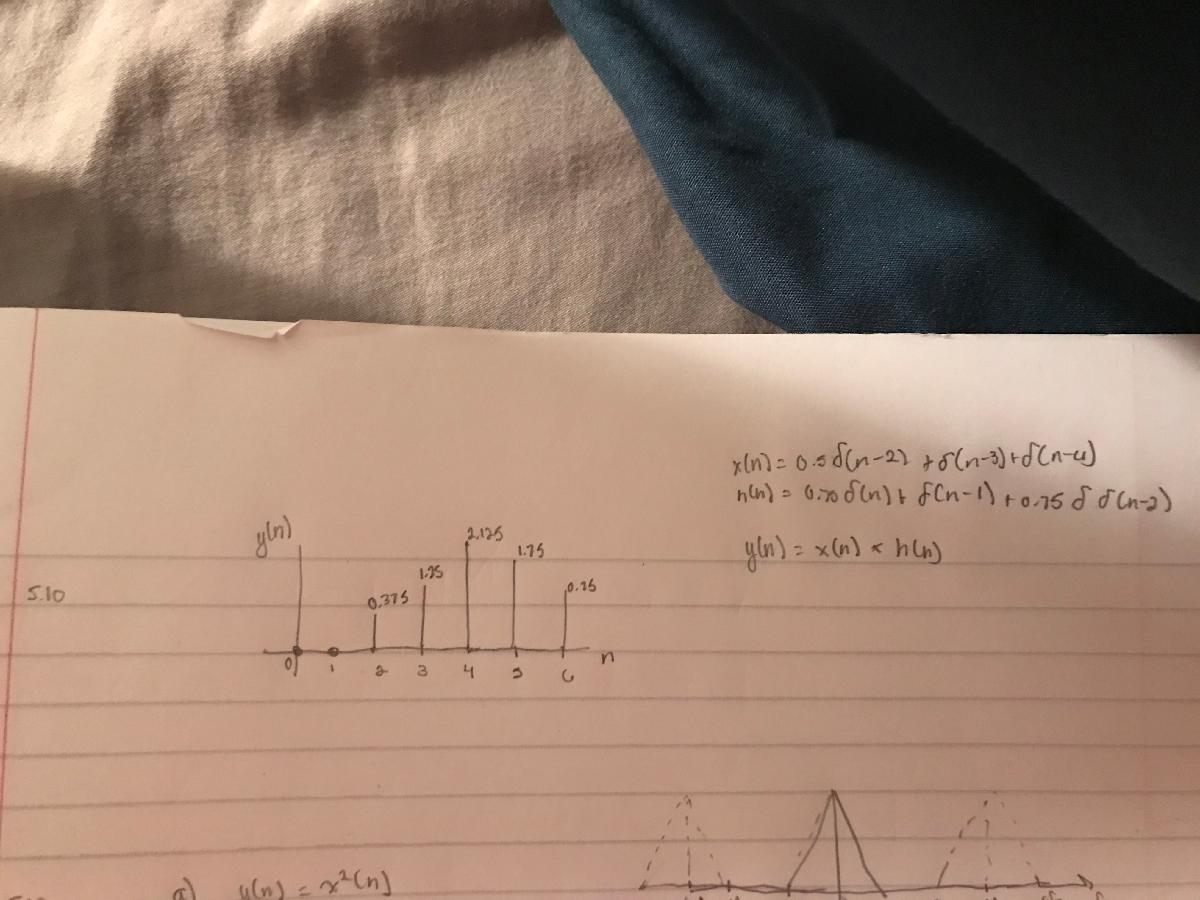

## Problem 11

Regarding the material in this chapter, it’s educational to revisit the idea of periodic sampling that was presented in Chapter 2. Think about a continuous x(t) signal in Figure P5-11(a) whose spectrum is depicted in Figure P5-11(b). Also, consider the continuous periodic infinitely narrow impulses, s(t), shown in Figure P5-11(c). Reference [28] provides the algebraic acrobatics to show that the spectrum of s(t) is the continuous infinitely narrow impulses, S(f), shown in Figure P5-11(d). If we multiply the x(t) signal by the s(t) impulses, we obtain the continuous y(t) = s(t)x(t) impulse signal shown by the arrows in Figure P5-11(e). 

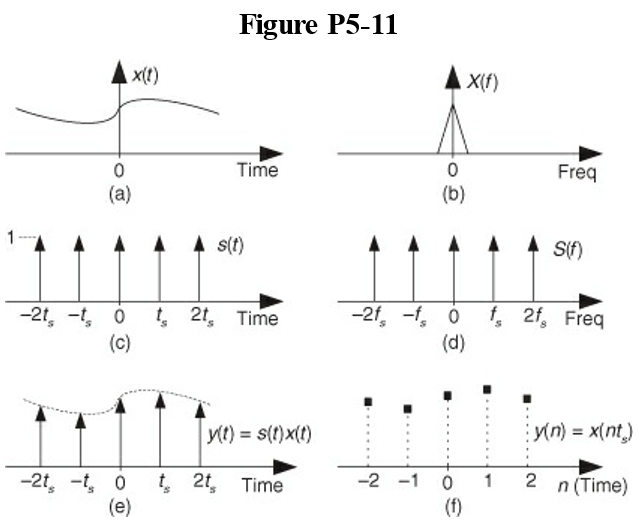

Now, if we use an analog-to-digital converter to represent those y(t) impulse values as a sequence of discrete samples, we obtain the y(n) sequence shown in Figure P5-11(f). Here is the problem: Briefly discuss what we learned in this Chapter 5 that tells us the spectrum of the y(n) samples comprises periodic replications of the X(f) in Figure P5-11(b). Your brief discussion should confirm the material in Chapter 2 which stated that discrete-time sequences have periodic (replicated) spectra. 

**Answer:**

The spectrum of the y(n) samples comprises of periodic replications of the X(f) because in Chapter 5 we learned that in Finite Impulse Response Filters, the filter's effect on the sequence x[n] is described in the frequency domain by the convolusion theorem:

Y(ω) = X(ω) *  H(ω)  and y[n] = x[n] * h[n] 

where   ω = 2*pi*f , changes the units of frequency (f ) to *cycles/sample* and the periodicity to 1. When the x[n] sequence has a known sampling-rate, fs *samples/second*,  the substitution ω =2πf / fs changes the units of frequency (f) to *cycles/second* and the periodicity to fs. The value ω =  π  corresponds to a frequency of   f= fs/2 Hz =1/2 *cycles/sample*, which is the Nyquiest frequency. 

## Problem 12

Now that we’re familiar with the powerful convolution theorem, think about the discrete system shown in Figure P5-12(a). 

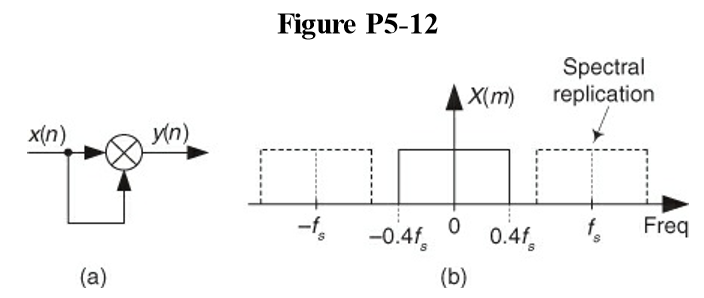

Given that x(n)’s spectrum is the X(m) shown in Figure P5-12(b): 

(a) Draw the Y(m) spectrum of sequence y(n). (We’re not worried about the vertical axis scale here, merely the frequency axis and spectral shape of Y(m).) 

(b) Will aliasing errors occur in the y(n) = x(n)2 output? (That is, will spectral replications in Y(m) overlap each other?)

 (c) What is x(n)’s maximum one-sided bandwidth that will avoid aliasing errors in y(n)? (Stated in different words, what is the maximum one-sided bandwidth of x(n) that will avoid overlapped spectral replications in Y(m)?) 

**Answer:**

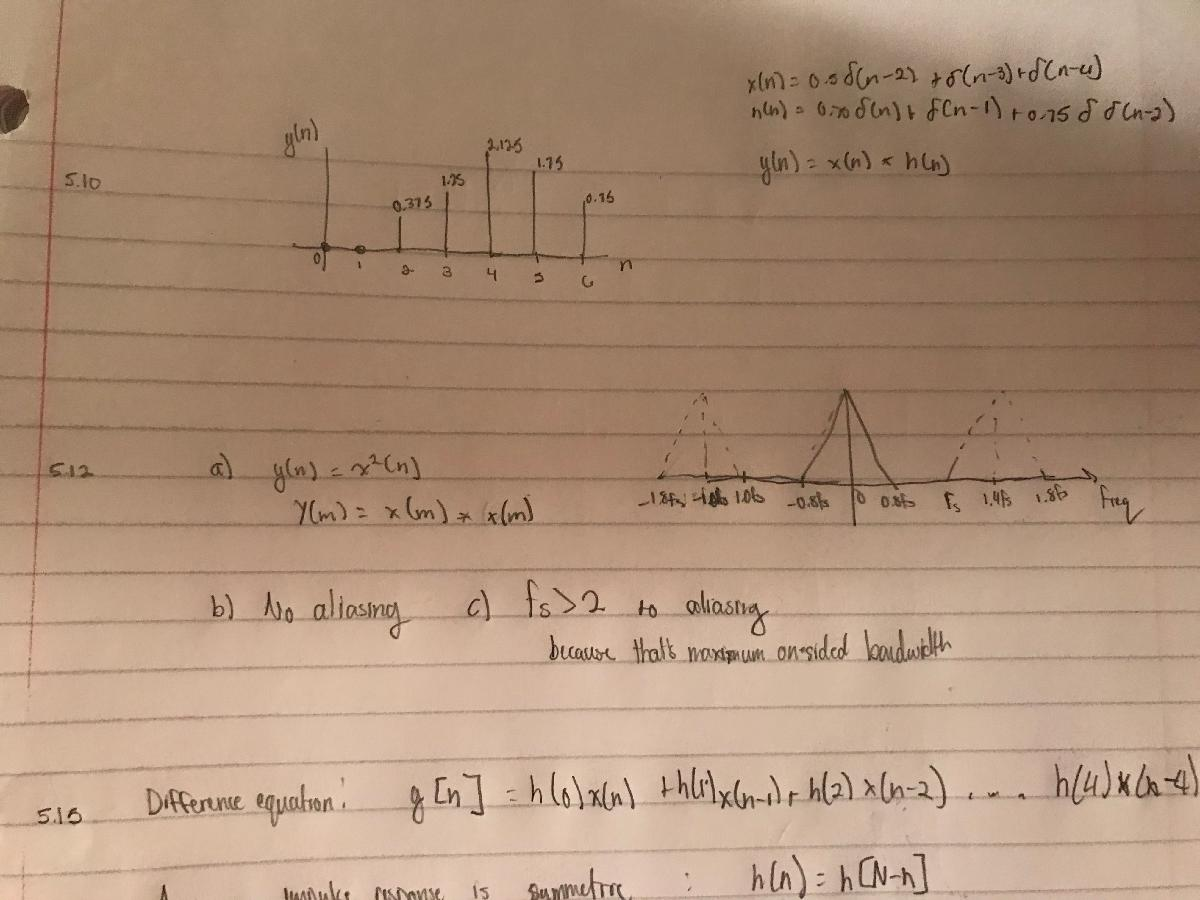

## Problem 13

 It’s likely that you have heard of the process called linear interpolation. It’s a computationally simple (but not terribly accurate) scheme for estimating sample values of a continuous function in between some given x(n) sample values of that function. For the x(n) time samples in Figure P513(a), linear interpolation is the process of computing the intermediate y(n) samples shown as the black squares in Figure P5-13(b). That is, the interpolated sample y(1) is the value lying on the center of the straight line connecting x(0) and x(1), the interpolated sample y(2) is the value lying on the center of the straight line connecting x(1) and x(2), and so on. Given this process of linear interpolation: 

(a) What is the equation defining y(n) in terms of the x(n) samples? 

(b) The implementation of linear interpolation is often called a filter because we build interpolators using tapped-delay line structures, just like standard FIR filter structures. Draw the block diagram of a linear interpolation filter that computes y(n) from the input x(n) sequence. 

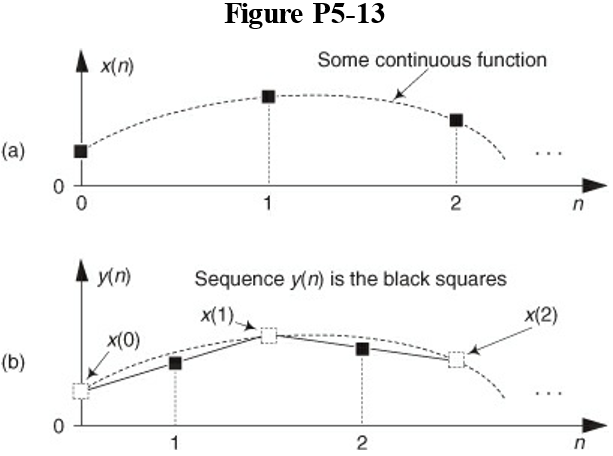

**Answer:**

**a) **y(n) = y(n+1) + (x(n) - x(n-1) ) (y(n+1) - y(n-1))/(x(n+1)-x(n-1))  

**b) **

## Problem 14

 Consider a linear-phase lowpass FIR filter whose coefficients are 

h1(k) = [−0.8, 1.6, 25.5, 47, 25.5, 1.6, −0.8], 

and whose DC gain, H1(0), is equal to 99.6. If we change those coefficients to

 h2(k) = [−0.8, 1.6, Q, 47, Q, 1.6, −0.8], 

we obtain a new DC gain equal to 103.6. What is the value of Q? 

**Answer: **

Q = 27.5

## Problem 15

 Figure P5-15 shows a linear-phase 5-tap FIR filter. 

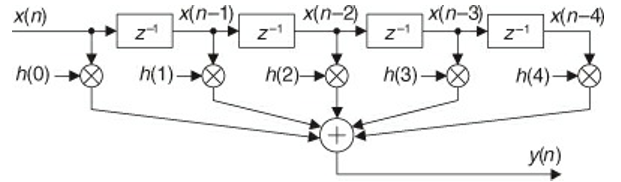

DSP engineers always seek to reduce the number of multipliers in their systems. Redesign the filter in Figure P5-15 to a form that reduces the number of necessary multiplications per output sample. Draw the block diagram of your new design.

 Hint: Write the difference equation for the y(n) output sequence, and recall the relationships between the filter’s coefficients. 

**Answer: **

    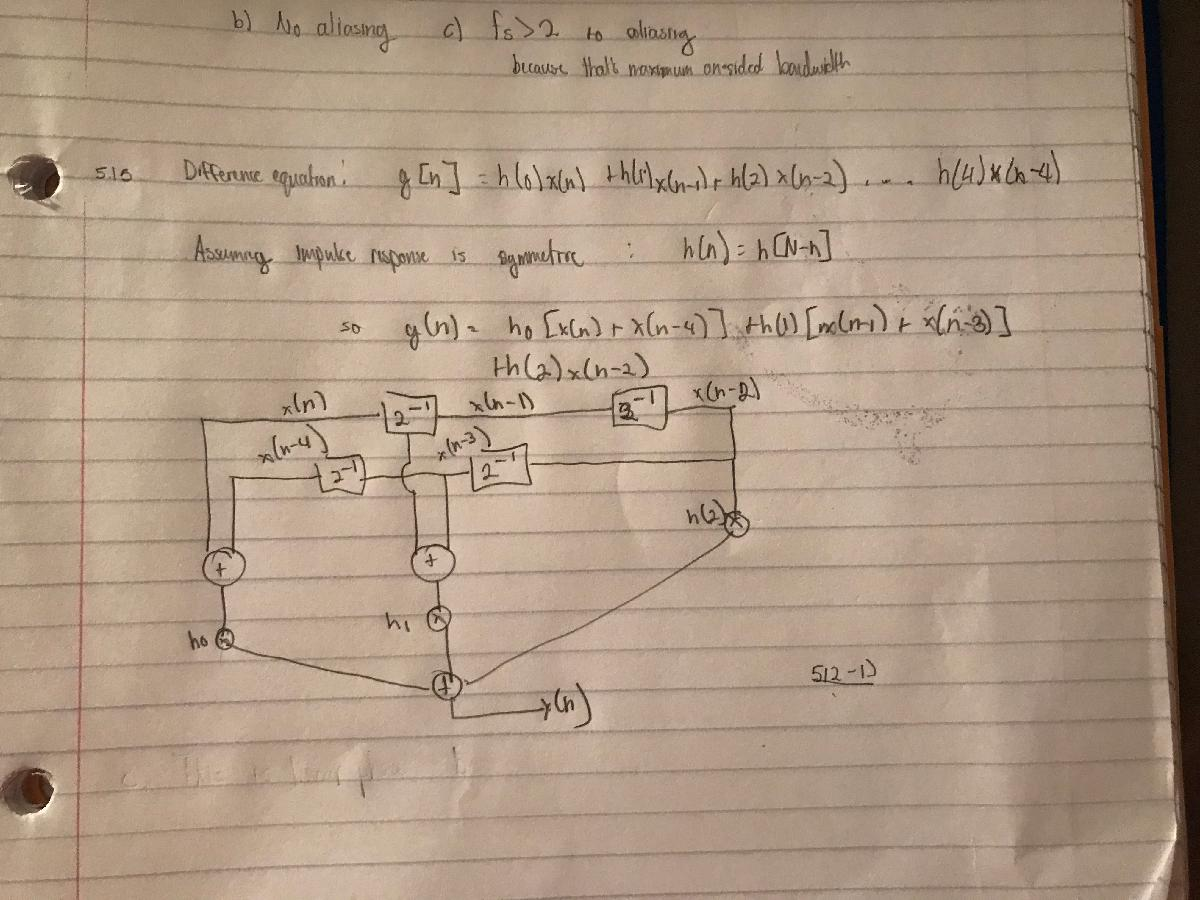

## Problem 16

The two linear-phase lowpass filters in Figure P5-16 have very similar frequency responses, but those responses are not identical except at a single frequency. If we replaced Filter h1 with Filter h2 to reduce our filtering computational workload, determine the frequency, ωo, where the two H1(ω) and H2(ω) frequency responses are equal. 

Hint: Begin by creating closed-form equations for H1(ω) and H2(ω) using the discrete-time Fourier transform (DTFT). 

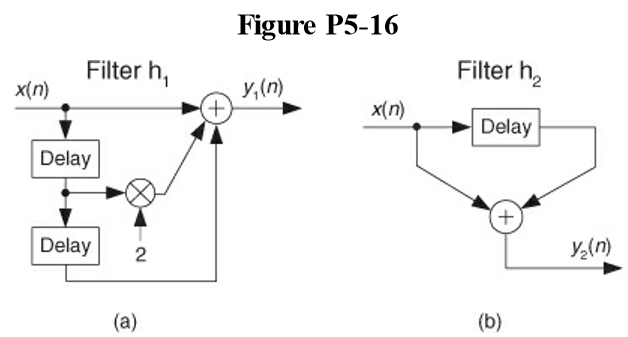

**Answer:**

## Problem 17

The following is a useful problem regarding the 3-tap nonrecursive FIR filter shown in Figure P5-17(a). The problem’s solution shows us how to design computationally efficient narrowbandnoise reduction filters. If |h1| ≤ 2, the filter will have an |H(ω)| frequency magnitude response having two nulls at ±ωn as shown in Figure P5-17(b). (Here, the frequency axis value of π radians/sample corresponds to a cyclic frequency of half the sample rate, fs/2.)

(a) Assume we have a low-frequency signal of interest that’s contaminated with high-level narrowband noise located at ±3.35 MHz when the sample rate is fs = 8.25 MHz as shown in Figure P5-17(c). To attenuate that noise, for what value of h1 will the 3-tap FIR filter’s nulls be located at the noise center frequency of ±3.35 MHz? Show your work.

 Hint: Use the discrete-time Fourier transform (DTFT) of the filter’s impulse response to create a closed-form equation for the filter’s H(ω) frequency response in terms of the coefficient h1 and frequency ω. Next, obtain the expression for h1 in terms of the filter’s null frequency ωn. 

(b) What is the DC gain (gain at zero Hz) of our 3-tap FIR filter? 

(c) Explain why the filter has a linear, or nonlinear, phase response.

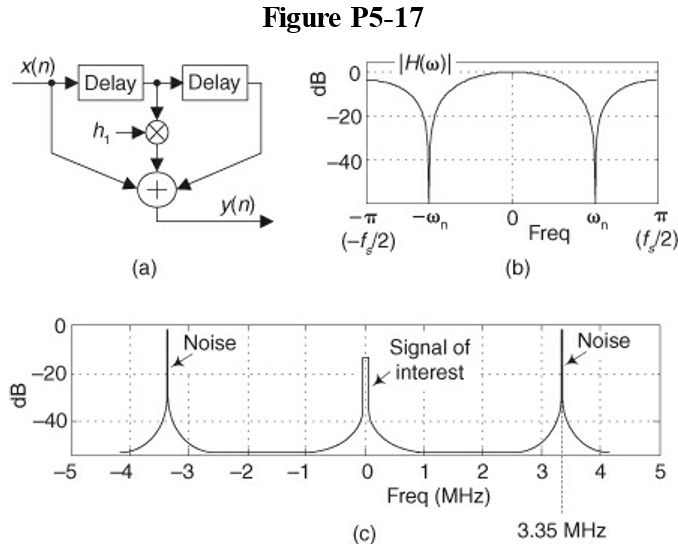

**Answer:**

**a) **h1 = 1.997

**b) **DC gain = 3 x 10^-3

**c) **linear phase because phase H(e^(jw)) = -w

## Problem 18

What characteristic must the coefficients of an FIR filter have to ensure that its frequencydomain phase response is a linear function of frequency (i.e., linear phase)?

**Answer: **

We know that the frequency domain phase is linear when the coefficients are symmetrical around the center.

## Problem 19

Quickfilter Technologies Inc. produces a tapped-delay line FIR filter chip (Part #QF1D512) that has an astounding N = 512 taps. When a new filter input sample is applied to the chip, how many addition operations must this chip perform to compute a single filter output sample? 

**Answer:**

512 addition operations must be performed

## Problem 20:

S20 = 255;
fs20 = 8*10^6;
Group_delay = (S20 - 1)/(2*fs20)

15uSeconds

## Problem 21:

time_delay = 600/(2*pi*400)

## Problem 22:

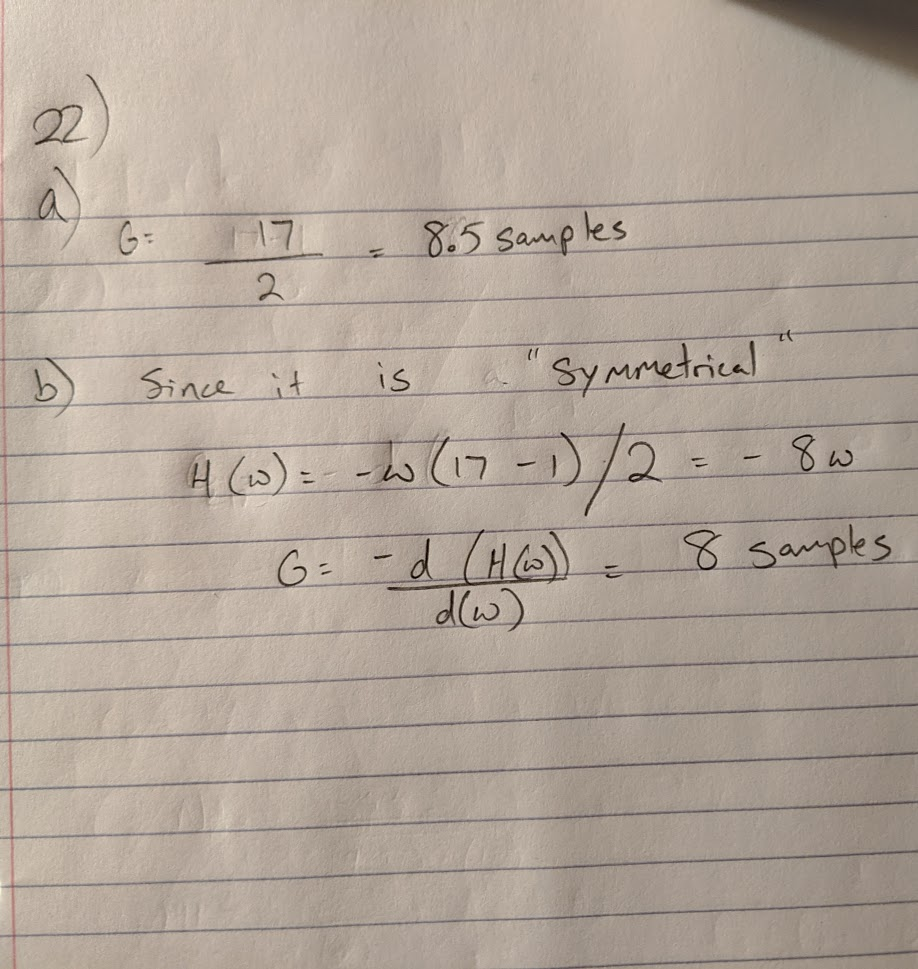

## Problem 23:

## Problem 24:

Time synchronization requires **4 unit delays**

## Problem 25:

## Problem 27:


$$191=\;\frac{55}{22*\left(f_{\mathrm{stop}} -f_{\mathrm{pass}} \right)}$$



$$\left(f_{\mathrm{stop}} -f_{\mathrm{pass}} \right)=\;0\ldotp 01308{\mathit{\mathbf{f}}}_{\mathit{\mathbf{s}}}$$


## Problem 28:

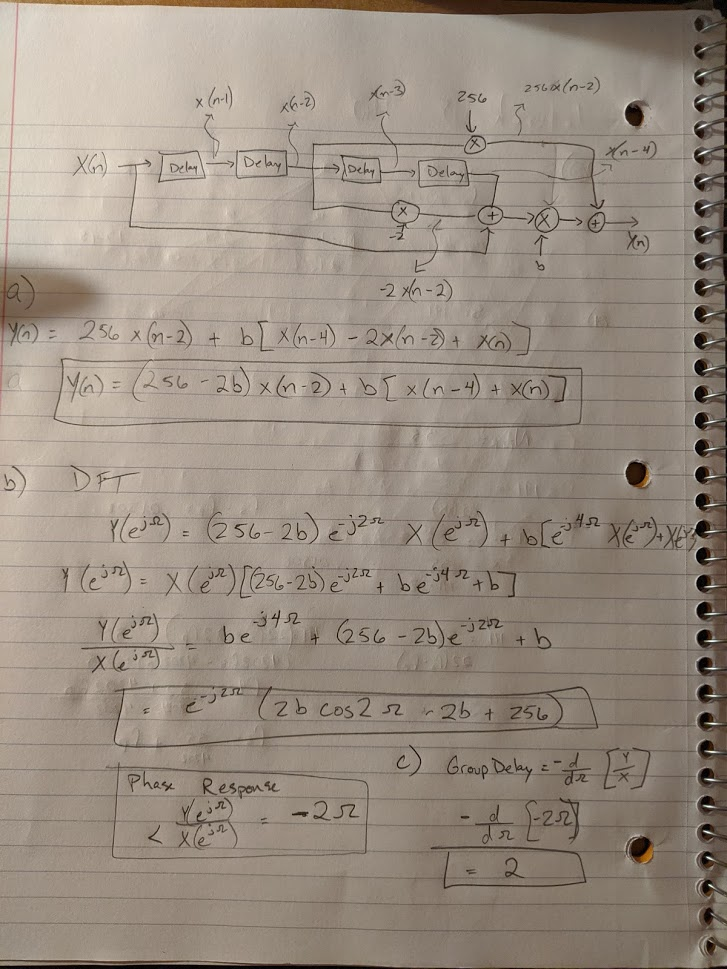

## Problem 29: